hand = imread('hand.jpg'); 
hand_64 = imresize(hand, [64 64]);

hand_ycbcr = RGB2YCbCr(hand_64);

%colorThresholder(hand_ycbcr);

%imwrite(BW, "hand_BM.png");

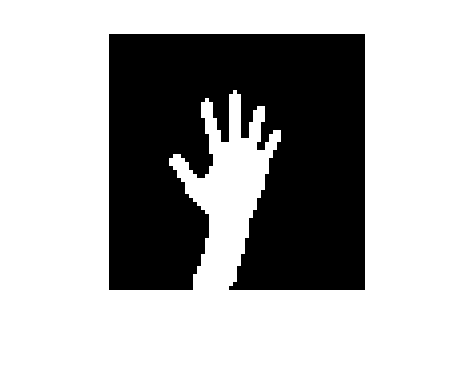

hand_BM = imread("hand_BM.png");
hand_MF = medfilt2(hand_BM, [3 3]);
figure
imshow(hand_MF, 'InitialMagnification', 400)

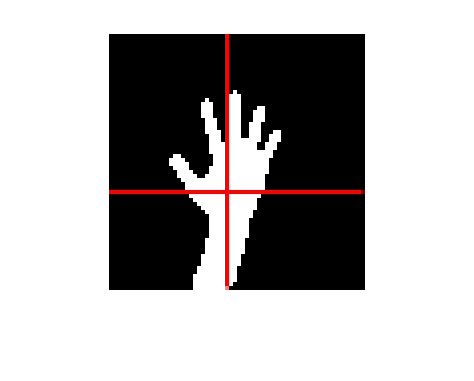

[x, y] = meshgrid(1:size(hand_MF, 2), 1:size(hand_MF, 1));
weightedx = x .* hand_MF;
weightedy = y .* hand_MF;
xcentre = sum(weightedx(:)) / sum(hand_MF(:));
ycentre = sum(weightedy(:)) / sum(hand_MF(:));

hand_ok = 255 * repmat(uint8(hand_MF), 1, 1, 3);
hand_CM = insertShape(hand_ok, 'line', [xcentre 0 xcentre 64], 'Color', 'r');
hand_CM = insertShape(hand_CM, 'line', [0 ycentre 64 ycentre], 'Color', 'r');
figure
imshow(hand_CM, 'InitialMagnification', 400)

function [out_pix] = RGB2YCbCr_pix(input)
    A = [[0.299 0.587 0.114];
         [-0.168736 -0.331264 0.5];
         [0.5 -0.418688 -0.081312]];
    B = [0; 128; 128];
    x = double(input(:,:)');
    out_pix = A*x + B;
end %RGB2YCbCr

function [out_img] = RGB2YCbCr(in_img)
out_img = zeros(size(in_img));
for i = 1:64
    for j = 1:64
        out_img(i, j, :) = RGB2YCbCr_pix(in_img(i, j, :));
    end %for
end %for
out_img = cast(out_img, 'uint8');
end